**Clear All Veriable**

clc; clear; close all; warning off all;

**Read Image From File**

P1.png is the image file contain all the ecg data

- crope the the image in desire place

main_image = imread('p1.png');
RGB = imcrop(main_image);
close all;

Thresholding the image to remove the background

I = RGB;

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 221.000;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.000;
channel2Max = 255.000;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.000;
channel3Max = 216.000;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

**Showing the threshholded image**

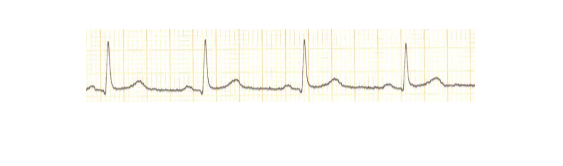

bw4 = bwareaopen(BW,0);
figure, imshow(RGB);

**Thining the image**

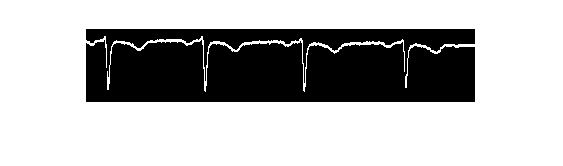

imbwaa=flip(bw4 ,1);
imbwaa= imbwaa;
imbwaa=bwmorph(imbwaa,'shrink',0);
imshow(imbwaa);

k = ~imbwaa;

**Digitilize the signal**

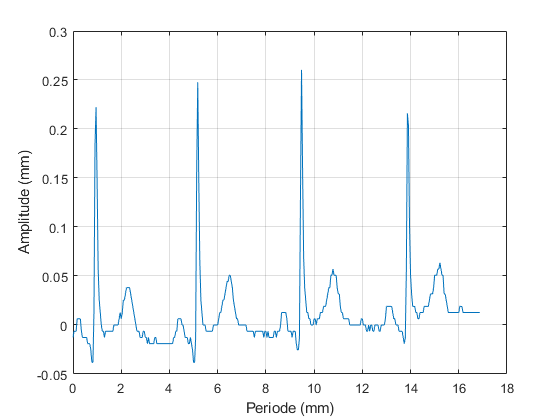


ld=0.00635;%faktor penyesuaian amplitudo dengan mm;

% ld=0.0483;%dengan mm 600dpi
target1R = 0 ;
%R = k;%(:,:,1);
matches1 = k == target1R ;
[x1, y1] = find(matches1);
 
DATA =[y1, x1];
sementara = unique(DATA,'rows');

lsementara = length(sementara);
jj = 1;
for ii = 1 : lsementara
    if ii > 1
        if sementara(ii, 1) == sementara(ii - 1, 1)
            continue
        end
    end
    if ii < lsementara
        if sementara(ii, 1) == sementara(ii + 1, 1)
            sementara2(jj,1) = sementara(ii, 1);
            sementara2(jj,2) = max(sementara(ii, 2),sementara(ii + 1, 2));
        else
            sementara2(jj, 1) = sementara(ii, 1);
            sementara2(jj, 2) = sementara(ii, 2);
        end
    else
            sementara2(jj, 1) = sementara(ii, 1);
            sementara2(jj, 2) = sementara(ii, 2);
    end
    jj = jj + 1;
end

HASIL_AKHIRAVF=sementara2(:,2);
HASIL_AKHIRAVF=(HASIL_AKHIRAVF)*ld;
maksim=max(HASIL_AKHIRAVF);
minim=min(HASIL_AKHIRAVF);
media=median((HASIL_AKHIRAVF));
HASIL_AKHIRAVF=HASIL_AKHIRAVF-media;
TG=maksim-minim;
fs=23;
%fs=1%400;%figure(3)
figure, plot([0:length(HASIL_AKHIRAVF)-1]/fs,HASIL_AKHIRAVF);
grid on
PJ=length(HASIL_AKHIRAVF)/fs;
xlabel('Periode (mm)');
ylabel('Amplitude (mm)');
datacursormode on 

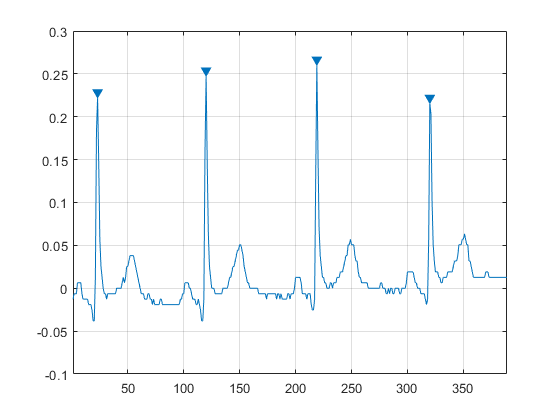

peak=findpeaks(HASIL_AKHIRAVF,'SortStr','descend');
%title('Plot')
csvwrite('test.dat',HASIL_AKHIRAVF);
%plot(peak)
figure,findpeaks(HASIL_AKHIRAVF,'MinPeakHeight',mean(HASIL_AKHIRAVF),'MinPeakDistance',60);